# ***P. putida***** KT2440 FBA Plotting**

## Initilization of COBRA

initCobraToolbox(false)



      _____   _____   _____   _____     _____     |
     /  ___| /  _  \ |  _  \ |  _  \   / ___ \    |   COnstraint-Based Reconstruction and Analysis
     | |     | | | | | |_| | | |_| |  | |___| |   |   The COBRA Toolbox - 2020
     | |     | | | | |  _  { |  _  /  |  ___  |   |
     | |___  | |_| | | |_| | | | \ \  | |   | |   |   Documentation:
     \_____| \_____/ |_____/ |_|  \_\ |_|   |_|   |   <a href="http://opencobra.github.io/cobratoolbox">http://opencobra.github.io/cobratoolbox</a>
                                                  | 

 > Checking if git is installed ...  Done (version: 2.24.1).
 > Checking if the repository is tracked using git ...  Done.
 > Checking if curl is installed ...  Done.
 > Checking if remote can be reached ...  Done.
 > Initializing and updating submodules (this may take a while)... Done.
 > Adding all the files of The COBRA Toolbox ...  Done.
 > Define CB map output... set to svg.
 > TranslateSBML is installed and working properly.
 > Configu

## Reading SBML & Outputing Spreadsheet

original_model = readCbModel('Pseudomonas Putida.xml');

The model contains 9 errors.

Error encountered during read.

Model contains non-unique metabolite names - consider renaming metabolites using checkCobraModelUnique
acmtsoxin[]


## Making a Copy of the Original Model

%copy the original model. This ensures that no changes are made in the original model
model = original_model;

## Adding Exogenous Reactions to the model

model = addReaction(model, 'TPA_EX', 'TPA[Extra_organism] <=> '); 
model = addReaction(model,'TPA_transport', 'TPA[Extra_organism] -> TPA[Cytosol]');

model = addReaction(model,'TPADO', 'TPA[Cytosol] + o2[Cytosol] + nadph[Cytosol] -> DCD[Cytosol] + nadp[Cytosol]');

model = addReaction(model,'TPHB', 'DCD[Cytosol] + nadp[Cytosol] -> 34dhbz[Cytosol] + nadph[Cytosol] + co2[Cytosol]');

## **Creating Baseline Model**

model = changeRxnBounds(model,'EX_glc__D_e',0,'l');
model_B = model;

## 3D plot: Growth vs Oxygen Uptake vs TPA Uptake

model_3Dplot = model_B;
uptake = -[1:1:20];
oxygen = [1:1:20];
growth = zeros(20,20); 

for i = 1:20
    for j = 1:20
        model_3Dplot = changeRxnBounds(model_3Dplot, 'TPA_EX', uptake(i), 'l'); 
        model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -oxygen(j), 'l');      
        putida_FBAsolution = optimizeCbModel (model_3Dplot, 'max'); 
        growth(i,j) = putida_FBAsolution.f;  
        model_3Dplot = model_B;
    end
end

growth

growth =     0.0146    0.0373    0.0601    0.0828    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831    0.0831
    0.0146    0.0373    0.0601    0.0828    0.1056    0.1283    0.1511    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705    0.1705
    0.0146    0.0373    0.0601    0.0828    0.1056    0.1283    0.1511    0.1738    0.1966    0.2193    0.2421    0.2578    0.2578    0.2578    0.2578    0.2578    0.2578    0.2578    0.2578    0.2578
    0.0146    0.0373    0.0601    0.0828    0.1056    0.1283    0.1511    0.1738    0.1966    0.2193    0.2421    0.2648    0.2876    0.3103    0.3331    0.3451    0.3451    0.3451    0.3451    0.3451
    0.0146    0.0373    0.0601    0.0828    0.1056    0.1283    0.1511    0.1738    0.1966    0.2193    0.2421    0.2648    0.2876    0.3103    0.3331    0.3558    0.3786    0.4013    0.4

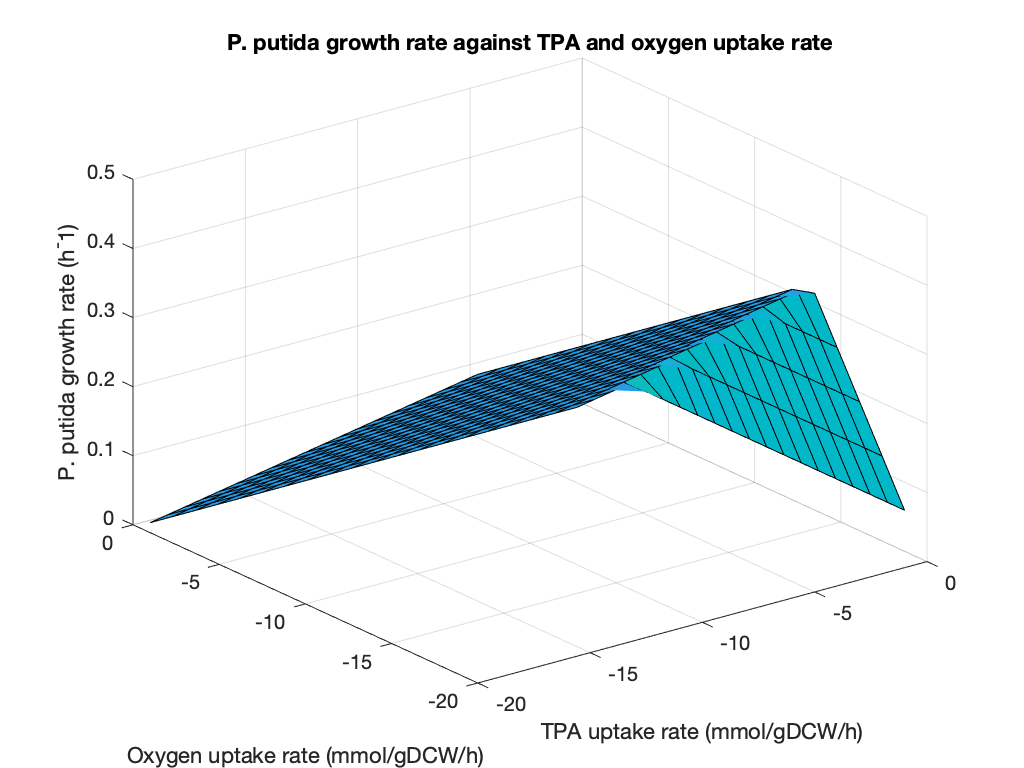

figure

surfl(uptake, -oxygen, growth');
xlabel('TPA uptake rate (mmol/gDCW/h)');
ylabel('Oxygen uptake rate (mmol/gDCW/h)');
zlabel('P. putida growth rate (h^-1)')
title('P. putida growth rate against TPA and oxygen uptake rate')

## 2D: Growth vs TPA Uptake

model_3Dplot = model_B;
alpha = [0.1:0.1:1];
uptake = -[1:10];
growth = zeros(10,1);
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -13.5, 'l');  

for i = 1:10
    model2 = model_3Dplot;
    model2 = changeRxnBounds(model2, 'TPA_EX', uptake(i), 'l'); 
    %optimization for biomass and get max flux
    putida_FBAsolution = optimizeCbModel (model2); 
    growth(i) = putida_FBAsolution.f;
end

alpha

alpha =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


uptake

uptake =     -1    -2    -3    -4    -5    -6    -7    -8    -9   -10


growth

growth =     0.0832
    0.1706
    0.2580
    0.2994
    0.2994
    0.2994
    0.2994
    0.2994
    0.2994
    0.2994


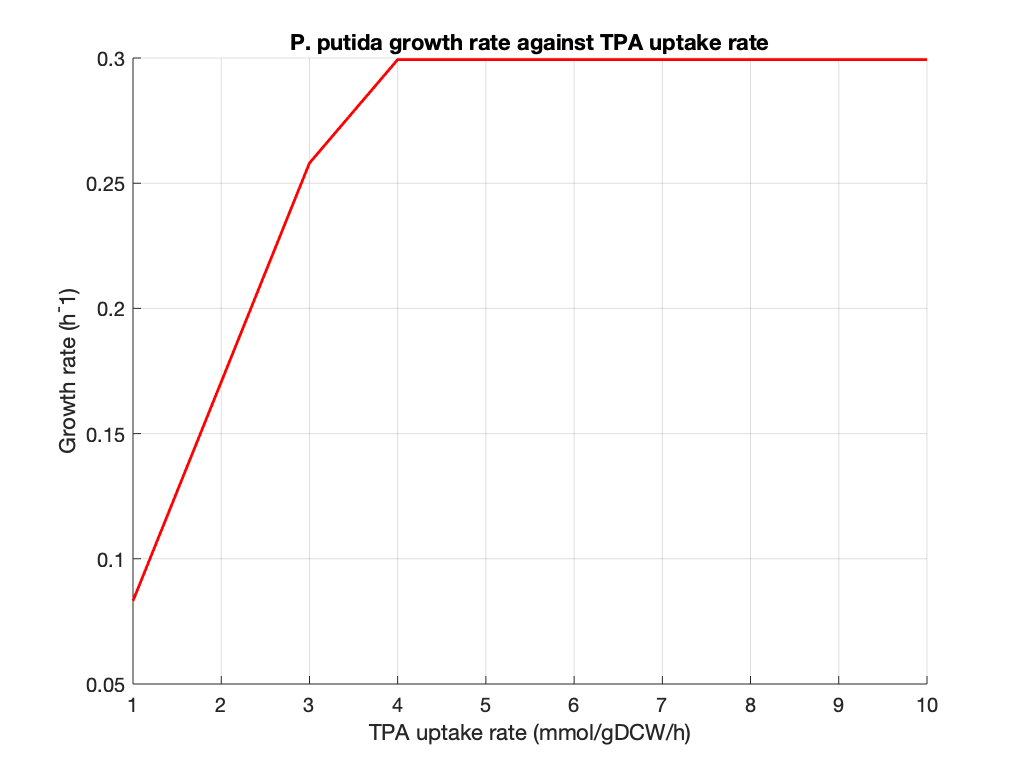


figure

%plot(-uptake, alpha, 'b')
hold on
grid on
plot(-uptake, growth, 'r','LineWidth',1.4)

xlabel('TPA uptake rate (mmol/gDCW/h)');
ylabel('Growth rate (h^-1)');
%legend('assumption', 'prediction')
title('P. putida growth rate against TPA uptake rate')

## 2D: Biomass Growth vs Carbon Source Uptake 

### (Glucose, TPA comparison)

model_3Dplot = model_B;
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -13.5, 'l'); 
alpha = [0.1:0.1:1];
uptake_tpa = -7.746 * alpha;
uptake_glucose = -10.328 * alpha;
growth_tpa = zeros(10,1);
growth_glucose = zeros(10,1);
model2 = changeObjective(model_3Dplot, 'BiomassKT2440_Core2'); 
 
for i = 1:10
    model2 = model_3Dplot;
    model2 = changeRxnBounds(model2, 'TPA_EX', uptake_tpa(i), 'l');   
    %optimization for biomass and get max flux
    putida_FBAsolution = optimizeCbModel (model2); 
    growth_tpa(i) = putida_FBAsolution.f;
    model2 = changeRxnBounds(model2, 'EX_glc__D_e', uptake_glucose(i), 'l');   
    %optimization for biomass and get max flux
    putida_FBAsolution = optimizeCbModel (model2); 
    growth_glucose(i) = putida_FBAsolution.f;
end

alpha

alpha =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


uptake

uptake =     -1    -2    -3    -4    -5    -6    -7    -8    -9   -10


growth

growth =     0.0832
    0.1706
    0.2580
    0.2994
    0.2994
    0.2994
    0.2994
    0.2994
    0.2994
    0.2994


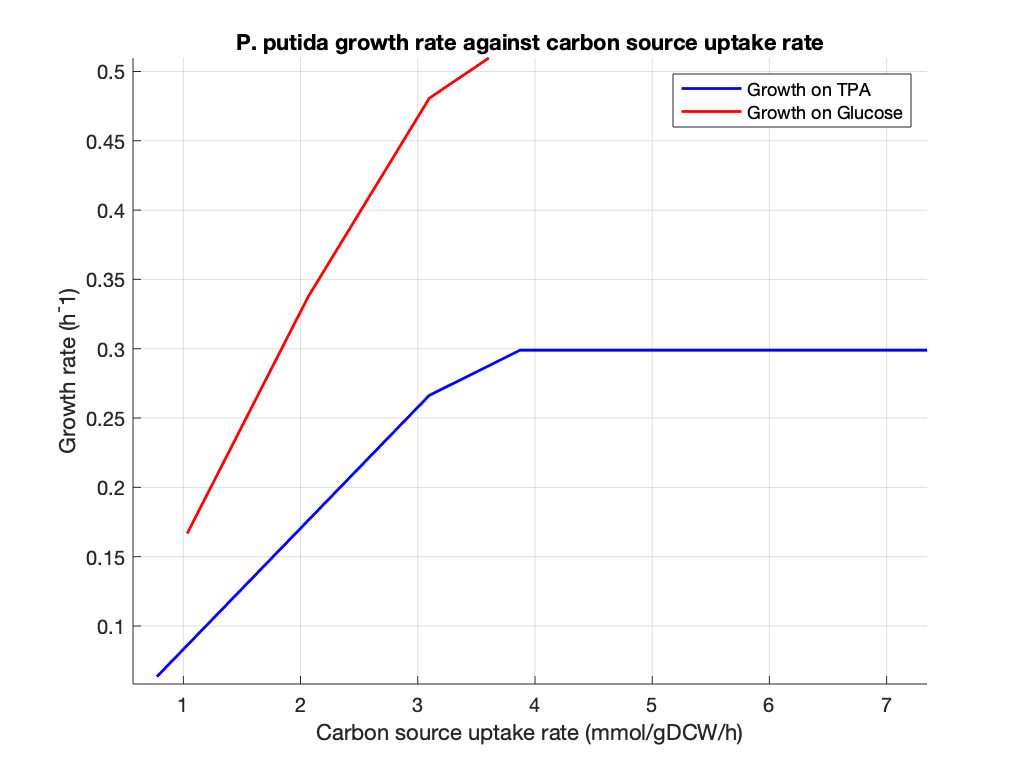


figure

grid on
hold on
plot(-uptake_tpa, growth_tpa, 'b','LineWidth',1.4)
hold on
plot(-uptake_glucose, growth_glucose, 'r','LineWidth',1.4)

xlabel('Carbon source uptake rate (mmol/gDCW/h)');
ylabel('Growth rate (h^-1)');
legend('Growth on TPA', 'Growth on Glucose')
title('P. putida growth rate against carbon source uptake rate');

## 2D: Growth vs Glucose Uptake

model_3Dplot = model_B;
alpha = [0.1:0.1:1];
uptake = -10.328 * alpha;
growth = zeros(10,1);
model_3Dplot = changeRxnBounds(model_3Dplot,'TPA_EX',0,'l');
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -13.5, 'l');  

for i = 1:10
    model2 = model_3Dplot;
    model2 = changeRxnBounds(model2, 'EX_glc__D_e', uptake(i), 'l'); 
    model2 = changeObjective(model2, 'BiomassKT2440_Core2'); 
    %optimization for biomass and get max flux
    putida_FBAsolution = optimizeCbModel (model2); 
    growth(i) = putida_FBAsolution.f;
end

alpha

alpha =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


uptake

uptake =    -1.0328   -2.0656   -3.0984   -4.1312   -5.1640   -6.1968   -7.2296   -8.2624   -9.2952  -10.3280


growth

growth =     0.0975
    0.1992
    0.3009
    0.4025
    0.5042
    0.6059
    0.6998
    0.7053
    0.7090
    0.7127


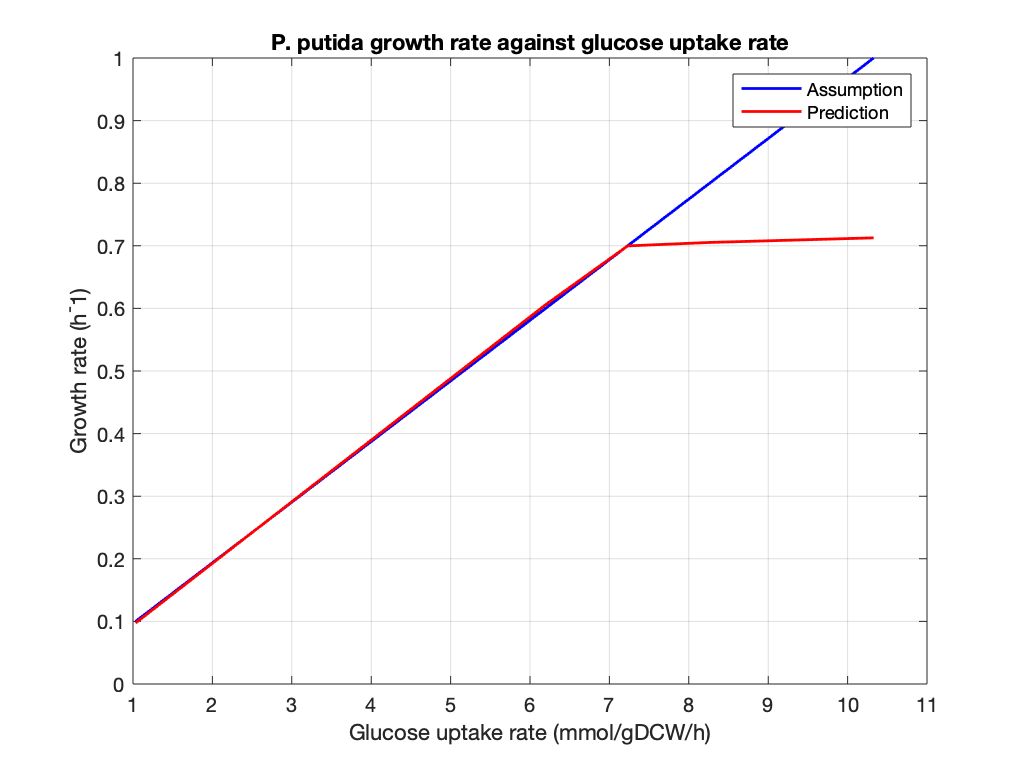


figure


plot(-uptake, alpha, 'b', 'LineWidth',1.4)
hold on
plot(-uptake, growth, 'r','LineWidth',1.4)
grid on

xlabel('Glucose uptake rate (mmol/gDCW/h)');
ylabel('Growth rate (h^-1)');
legend('Assumption', 'Prediction')
title('P. putida growth rate against glucose uptake rate')

## 2D: Growth vs Oxygen Uptake

model_3Dplot = model_B;
uptake = [1:50];
growth = zeros(50,1);
model_3Dplot = changeRxnBounds(model_3Dplot,'TPA_EX',0,'l');
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_glc__D_e', -8, 'l');  

for i = 1:50
    model2 = model_3Dplot;
    model2 = changeRxnBounds(model2, 'EX_o2_e', -uptake(i), 'l'); 
    model2 = changeObjective(model2, 'BiomassKT2440_Core2'); 
    %optimization for biomass and get max flux
    putida_FBAsolution = optimizeCbModel (model2); 
    growth(i) = putida_FBAsolution.f;
end

alpha

alpha =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


uptake

uptake =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


growth

growth =     0.0441
    0.1014
    0.1587
    0.2160
    0.2706
    0.3216
    0.3727
    0.4237
    0.4747
    0.5258


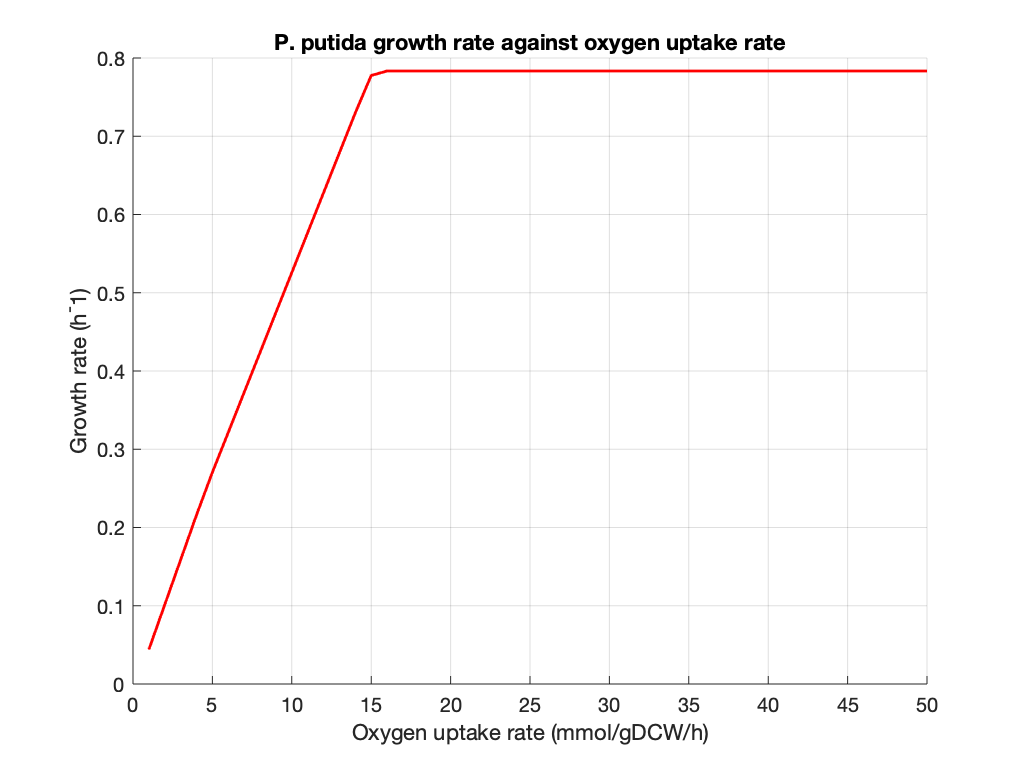


figure

hold on
plot(uptake, growth, 'r','LineWidth',1.4)
grid on

xlabel('Oxygen uptake rate (mmol/gDCW/h)');
ylabel('Growth rate (h^-1)');
title('P. putida growth rate against oxygen uptake rate')

## Lactate Production

model_lac = model_B;
model_lac = changeRxnBounds(model_lac, 'TPA_EX', -7.5, 'l'); 
model_lac = changeRxnBounds(model_lac, 'EX_o2_e', -20, 'l');
model_lac = changeObjective(model_lac, 'BiomassKT2440_Core2'); 
putida_FBAsolution = optimizeCbModel (model_lac, 'max')

putida_FBAsolution = struct with fields:
    origStatText: []
               f: 0.4474
               v: [2933×1 double]
               y: [2158×1 double]
               w: [2933×1 double]
               s: [2158×1 double]
          solver: 'glpk'
       algorithm: 'default'
            stat: 1
        origStat: 5
            time: 0.2575
           basis: []
          vars_v: []
               x: [2933×1 double]


model_lac = changeRxnBounds(model_lac, 'BiomassKT2440_Core2', 0.2, 'l'); 
model_lac = changeObjective(model_lac, 'EX_lac__D_e');
lac_FBAsolution = optimizeCbModel (model_lac, 'max'); 
lac = lac_FBAsolution.f

lac = 8.2113

## 2D: Lactate Production vs TPA Uptake

model_3Dplot = model_B;
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -13.5, 'l'); 
model_3Dplot = changeRxnBounds(model_3Dplot, 'BiomassKT2440_Core2', 0.2, 'l'); 

alpha = [0.1:0.1:1];
uptake_tpa = -7.746 * alpha;
production_tpa = zeros(10,1);
model_3Dplot = changeObjective(model_3Dplot, 'EX_lac__D_e'); 
 
for i = 1:10
    model2 = model_3Dplot;
    model2 = changeRxnBounds(model2, 'TPA_EX', uptake_tpa(i), 'l');   
    %optimization for biomass and get max flux
    putida_FBAsolution = optimizeCbModel (model2); 
    production_tpa(i) = putida_FBAsolution.f;
end

alpha

alpha =     0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000


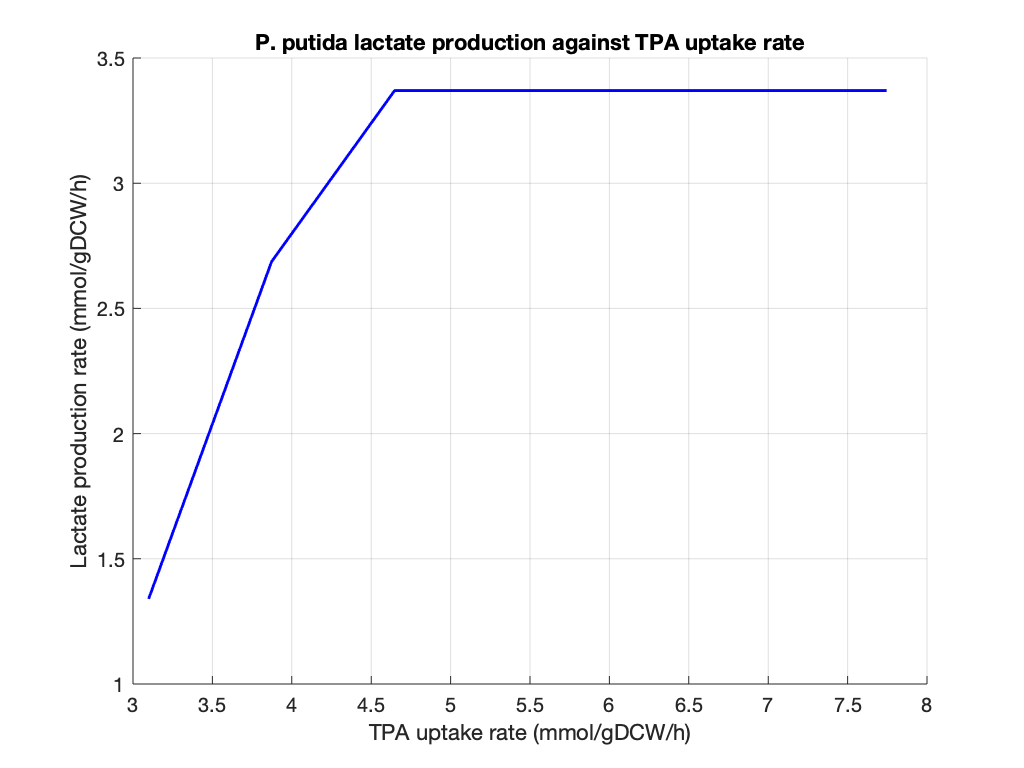

figure

grid on
hold on
plot(-uptake_tpa, production_tpa, 'b','LineWidth',1.4)

xlabel('TPA uptake rate (mmol/gDCW/h)');
ylabel('Lactate production rate (mmol/gDCW/h)');
title('P. putida lactate production against TPA uptake rate');

## 3D plot: Lactate Scretion vs TPA Uptake vs Biomass Growth

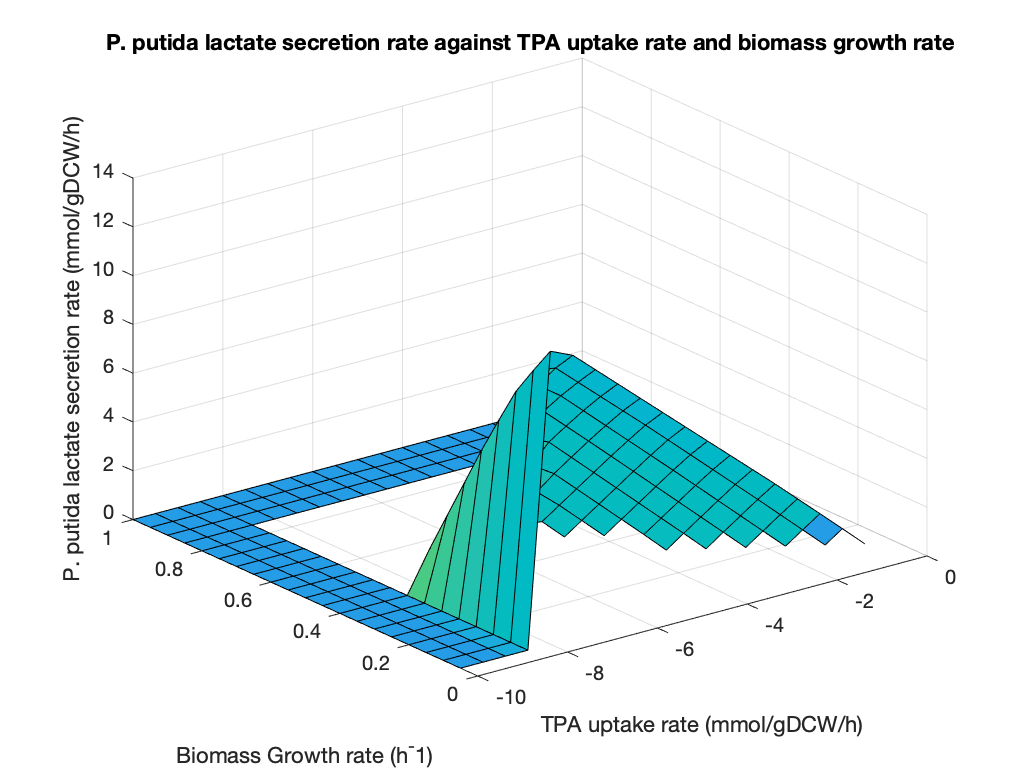

model_3Dplot = model_B;
uptake = -[0.5:0.5:10];
biomass = [0.05:0.05:1];
lac = zeros(20,20); 
model_3Dplot = changeRxnBounds(model_3Dplot, 'EX_o2_e', -20, 'l');
model_3Dplot = changeObjective(model_3Dplot, 'EX_lac__D_e');

for i = 1:16
    for j = 1:16
        model_3Dplot = changeRxnBounds(model_3Dplot, 'TPA_EX', uptake(i), 'l'); 
        model_3Dplot = changeRxnBounds(model_3Dplot, 'BiomassKT2440_Core2', biomass(j), 'l');      
        putida_FBAsolution = optimizeCbModel (model_3Dplot, 'max'); 
        lac(i,j) = putida_FBAsolution.f;  
    end
end

figure

surfl(uptake, biomass, lac');
xlabel('TPA uptake rate (mmol/gDCW/h)');
ylabel('Biomass Growth rate (h^-1)');
zlabel('P. putida lactate secretion rate (mmol/gDCW/h)')
title('P. putida lactate secretion rate against TPA uptake rate and biomass growth rate')

## Sinlge Gene Deletion

model_SGD = model_B;
model_SGD = changeRxnBounds(model_SGD, 'EX_o2_e', -20, 'l'); 
model_SGD = changeRxnBounds(model_SGD, 'TPA_EX', -8, 'l'); 
model_SGD = changeRxnBounds(model_SGD, 'BiomassKT2440_Core2', 0.2, 'l');
model_SGD = changeRxnBounds(model_SGD, 'BiomassKT2440_Core2', 0.3, 'u');
model_SGD = changeObjective(model_SGD, 'EX_lac__D_e');
[prodRatio, prodRateKO, prodRateWT, hasEffect, delRxns, fluxSolution] = singleGeneDeletion(model_SGD);

Single gene deletion analysis in progress ...
100%    [........................................]


max(prodRateKO)

ans = 8.2132